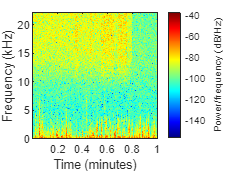

clear
[y1,Fs] = audioread("forensisktljud.wav");
spectrogram(y1(:,2),441,220,1000,Fs,"yaxis");

%Kolla på del av ljudet
from = 3; %sekund
to = 15; %sekund
%y = y1(from*Fs:to*Fs,:);
y=y1;




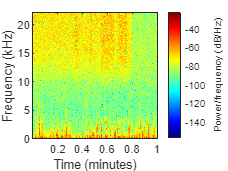

result = y ./max(abs(y));

result = result.*2;
spectrogram(result(:,2),441,220,1000,Fs,"yaxis");

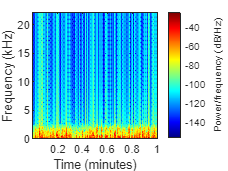


result = sgolayfilt(result,3,27);

result=highpass(result,60,Fs);
result=lowpass(result,190,Fs);

for i=1:length(result)
        aboVal = max(abs(result(i,1)), abs(result(i,2)));
        result(i,1) = result(i,1) * (2 - aboVal);
        result(i,2) = result(i,2) * (2 - aboVal);
end

spectrogram(result(:,2),441,220,1000,Fs,"yaxis");

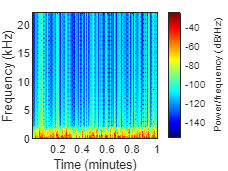


result = sgolayfilt(result,3,27);

result=highpass(result,60,Fs);
result=lowpass(result,190,Fs);



spectrogram(result(:,2),441,220,1000,Fs,"yaxis");

sound(result,Fs);

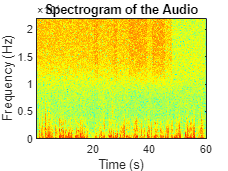


[y, Fs] = audioread("forensisktljud.wav");

% Define parameters for the spectrogram
windowSize = 512;   % Size of the analysis window
overlap = 256;      % Overlap between consecutive windows
nfft = 1000;         % Number of FFT points

% Create the spectrogram
[S, F, T] = spectrogram(y(:,2), windowSize, overlap, nfft, Fs);

% Plot spectrogram
figure;
imagesc(T, F, 10*log10(abs(S))); % Convert to dB scale
axis xy; % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram va ljudet');

% You can also adjust the colormap for better visualization
colormap('jet'); % Use a colormap of your choice

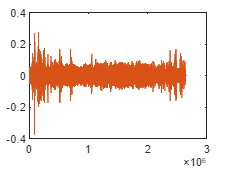


plot(y);

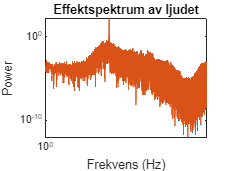

[y, Fs] = audioread("forensisktljud.wav");

nfft = 1000;  
windowSize = 512; 

m = length(y);
n = pow2(nextpow2(m));
variabelNamn = fft(y,n);

power = variabelNamn.*conj(variabelNamn)/n;

f = (0:n-1)*(Fs/n);
loglog(f,power);

xlim([1,20000]);
ylabel('Power');
xlabel('Frekvens (Hz)');
title('Effektspektrum av ljudet');